% Define the file name of the CSV file
filename = '50mv_milo2.csv';

% Read the CSV file using readtable
data = readtable(filename);

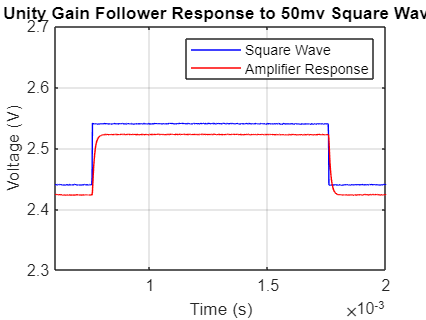


% Extract the time and voltage columns from the data
% Use the correct column names based on your CSV file
time = data.("Time_s_"); % Time column
voltage_ch1 = data.("Channel1_V_"); % Voltage column for Channel 1
voltage_ch2 = data.("Channel2_V_"); % Voltage column for Channel 2

% Plot the data
figure; % Create a new figure
plot(time, voltage_ch1, 'b-', 'DisplayName', 'Square Wave'); % Plot the voltage vs. time for Channel 1
hold on; % Hold the current plot so that we can add more data to it
plot(time, voltage_ch2, 'r-', 'DisplayName', 'Amplifier Response'); % Plot the voltage vs. time for Channel 2
 % Release the hold on the current plot
xlabel('Time (s)'); % Label the x-axis
ylabel('Voltage (V)'); % Label the y-axis
title('Unity Gain Follower Response to 50mv Square Wave'); % Add a title to the plot
legend('show'); % Show the legend
ylim([2.3 2.7])
xlim([0.6e-3 2e-3])
grid on; % Add a grid to the plot
hold off